## **Problem 15:**

**Unable to properly comprehend and execute a procedure to solve the question, would appreciate example done in class**

## **Problem 16:**

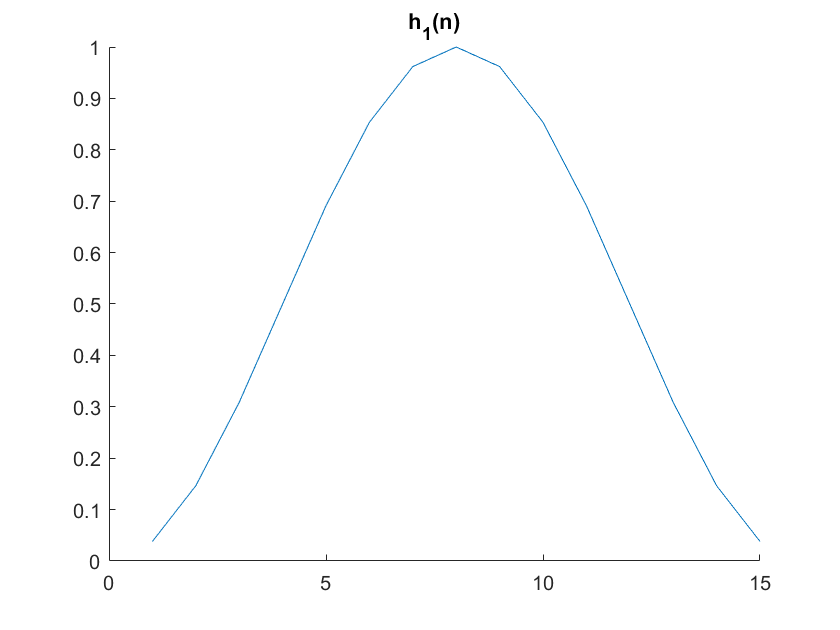

clf
n = 1:47;
figure
for n = 1 : 15
    h1(n) = 0.5-.5*(cos((2*pi*n)/16));
    hold on
    plot(h1)
end
title("h_1(n)")
hold off

**(A) **$h_1 \left(n\right)$ is made of two signals, a DC signal of 0.5, and a signal $-0\ldotp 5\;\mathrm{cos}\left(\frac{2\pi n}{16}\right)$. $h_1 \left(n\right)$ looks the way it does, because it has a positive component of 0.5 meaning the y value is offset by 0.5, and there is a frequency over time that is shifting up and down from 0 to 1 by subtracting the resultant of the signal.

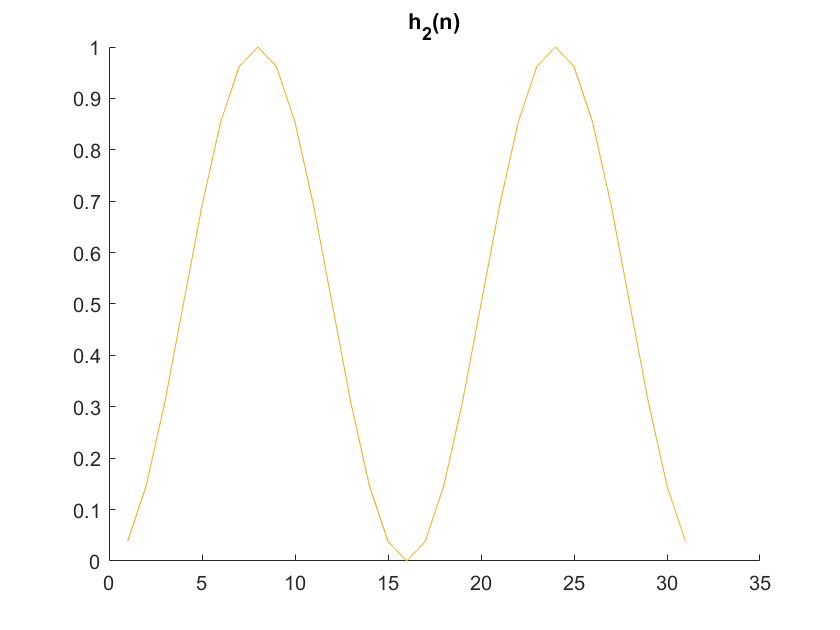

clf
figure
for n = 1 : 31
    h2(n) = .5 -.5*(cos((2*pi*n)/16));
    hold on
    plot(h2)
end
title("h_2(n)")
hold off

**(B)**

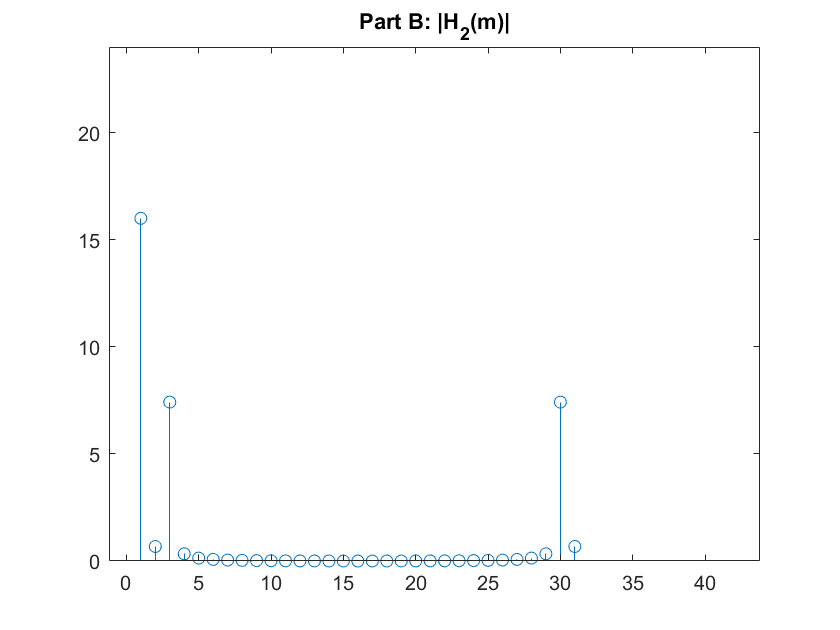

figure
f=abs(real(fft(h2)));
stem(1:31,f)
xlim([-1.2 43.8])
ylim([0.0 24.0])
title("Part B: |H_2(m)|")

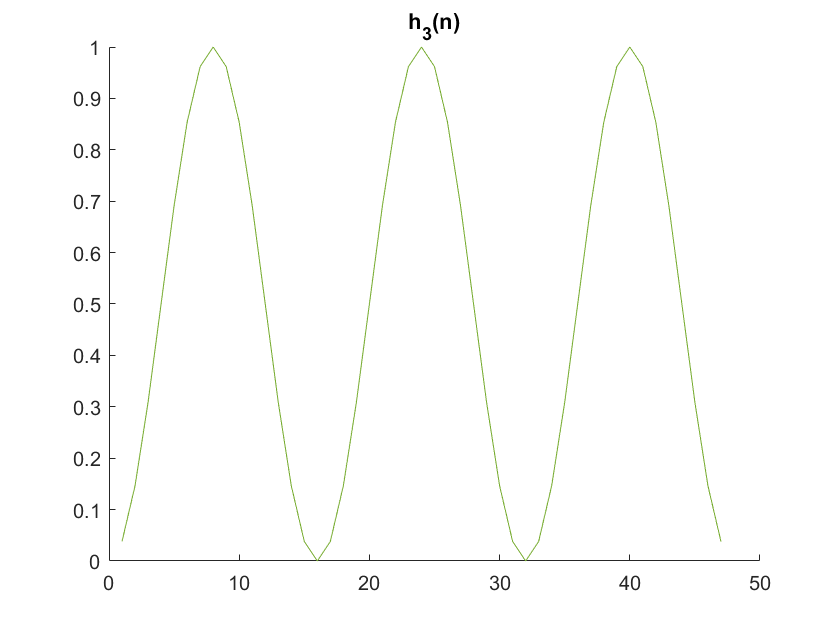

clf
figure
for n = 1 : 47
    h3(n) = .5 -.5*(cos((2*pi*n)/16));
    hold on
    plot(h3)
end
title("h_3(n)")
hold off

**(C)**

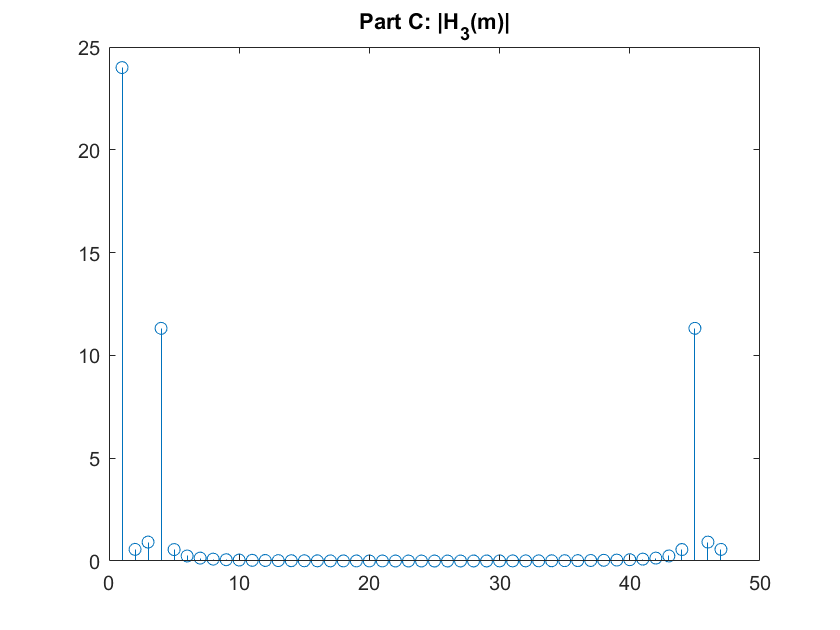

figure
f=abs(real(fft(h3)));
stem(1:47,f)
title("Part C: |H_3(m)|")

**(D)**

**“K repetitions of an h1(n) sequence result in an extended-length time sequence whose spectral magnitudes have K−1 ...”**

**            GAIN**

## **Problem 17:**

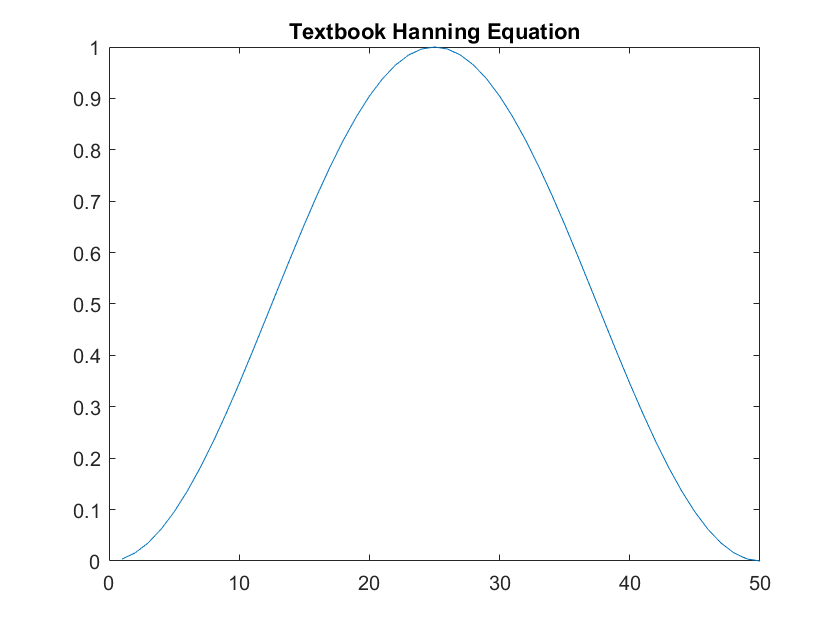

N = 50;
hann1 = zeros(1,N);
hann2 = zeros(1,N);

for n = 1:N
    hann1(n) = 0.5 - 0.5*cos((2*pi*n)/N);
    hann2(n) = sin((pi*n)/N) .^2;
end
figure
plot(hann1)
title('Textbook Hanning Equation')

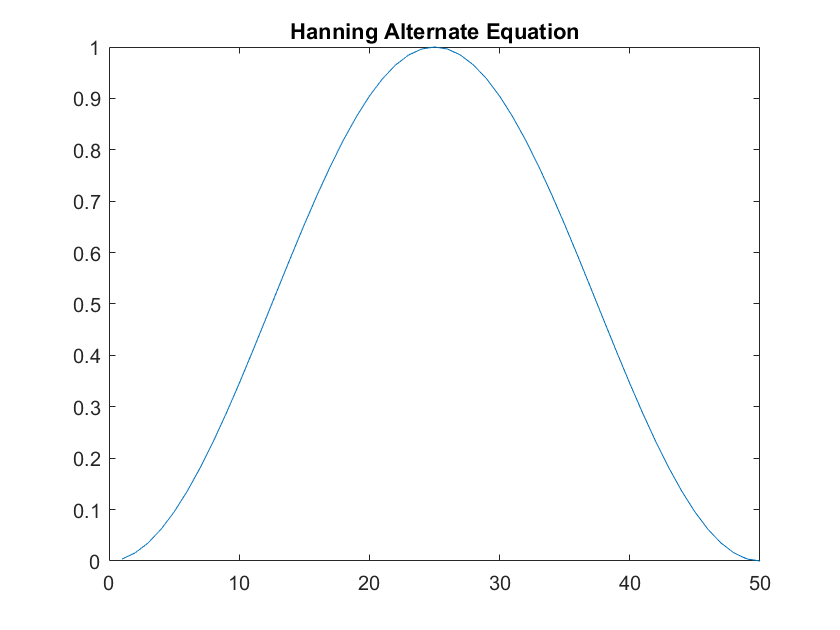

figure
plot(hann2)
title('Hanning Alternate Equation')

## **Problem 18:**

A Continuous fourier transform is performed in which there are a number of padded zeros in the data. The transform creates a centered wave form, where as Q increases the observer will see graphical points that resemble the wave itself.

## **Problem 20:**

SNR_N = 10*log(1000000/100)

SNR_N = 92.1034

Gain of 92.103 in their signal

## Problem 21

**(A)**

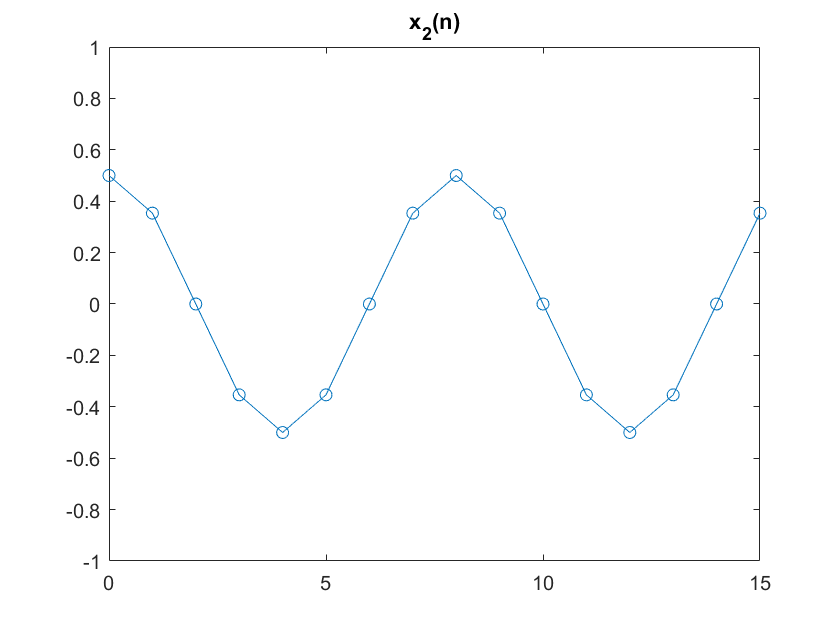

x2 = [0 0 4 0 0 0 0 0 0 0 0 0 0 0 4 0];
t = 0:15;
ycomp = ifft(x2);
yreal = real(ycomp);
plot(t,yreal,'-o')
title 'x_2(n)'
ylim([-1 1]);

**(B)**

This plot looks identical to the original $x_1 \left(n\right)$ sequence, and comparitively looks the same as x(t). It is however dampened and only reaches a range of -0.6 to +0.6.

## Problem 22

There is a useful spectrum analysis process, discussed in Chapter 13, that uses the results of an N-point DFT, X(m), and requires us to compute 

S = P · X(0) − Q · X(N−1) − Q · X(1) 

where P and Q are scalar constants. Value S is the sum of three complex numbers. If we represent the three DFT samples in rectangular form, we can write 

S = P · [a + jb] − Q · [c + jd] − Q · [e + jg]. 

In the general case, the above expression for S requires six real multiply operations. If the DFT’s

x(n) input sequence is real-only, what is the equation for S that requires fewer than six real multiplies? Show your work.

**UNSURE as to what this question pertains to, or is asking, I found information in chapter 13 section 4 about changing from multiplication to addition/subtraction. Although, I failed to find how to accomplish this question.**